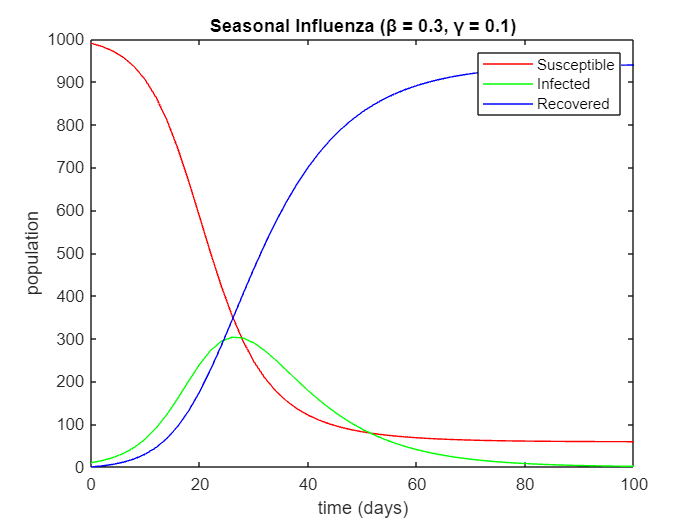

%Part 2

h = [1,2];
S0 = 990;
I0 = 10;
R0 = 0;
T0 = 0;
T = 100;

%influenza, COVID-19, Measeles
beta = [0.3,1,2]; 
gamma = [0.1,0.1,0.2];


influenzaTrue = modelSIR(S0,I0,R0,T0,T,h(1),beta(1),gamma(1)); %h = 1
influenza = modelSIR(S0,I0,R0,T0,T,h(2),beta(1),gamma(1)); %h = 2


plot(influenza(1,:),influenza(2,:),'r',influenza(1,:),influenza(3,:),'g',influenza(1,:),influenza(4,:),'b')
xlabel('time (days)');
ylabel('population');
legend('Susceptible','Infected','Recovered');
title('Seasonal Influenza (β = 0.3, γ = 0.1)');

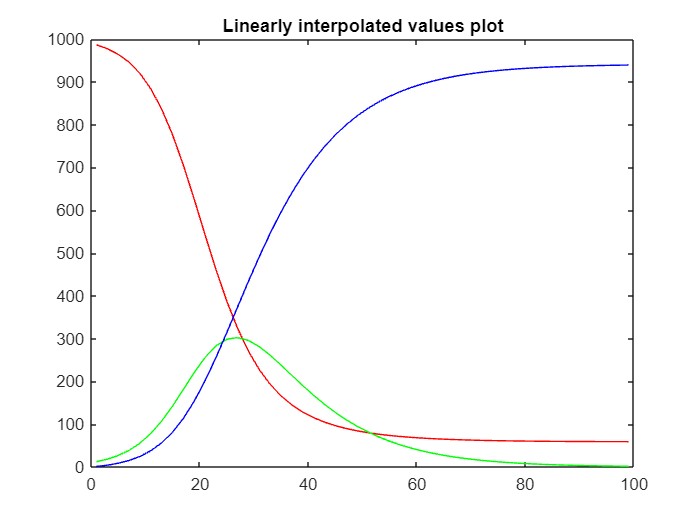


n = (T-T0)/h(2);
daysInter = 1:h(2):T;
susepInter = zeros(1,size(daysInter,2)); 
infectInter = zeros(1,size(daysInter,2));
recoverInter = zeros(1,size(daysInter,2));

for i=1:n  % Linear Interpolation
    susepInter(i) = ((daysInter(1,i) - influenza(1,i+1))/(influenza(1,i) - influenza(1,i+1)))*influenza(2,i) + ((daysInter(1,i) - influenza(1,i))/(influenza(1,i+1) - influenza(1,i)))*influenza(2,i+1);
    infectInter(i) = ((daysInter(1,i) - influenza(1,i+1))/(influenza(1,i) - influenza(1,i+1)))*influenza(3,i) + ((daysInter(1,i) - influenza(1,i))/(influenza(1,i+1) - influenza(1,i)))*influenza(3,i+1);
    recoverInter(i) = ((daysInter(1,i) - influenza(1,i+1))/(influenza(1,i) - influenza(1,i+1)))*influenza(4,i) + ((daysInter(1,i) - influenza(1,i))/(influenza(1,i+1) - influenza(1,i)))*influenza(4,i+1);
end

plot(daysInter(1,1:end), susepInter, 'r')
hold on
plot(daysInter(1,1:end), infectInter, 'g')
plot(daysInter(1,1:end), recoverInter, 'b')
title("Linearly interpolated values plot")
hold off

EL2susepLinear = sqrt(sum((influenzaTrue(2,2:2:T)-susepInter).^2)./n)  % Error for susceptible (flu)

EL2susepLinear = 0.6513

EL2infectLinear = sqrt(sum((influenzaTrue(3,2:2:T)-infectInter).^2)./n)  % Error for infected (flu)

EL2infectLinear = 0.5041

EL2recoverLinear = sqrt(sum((influenzaTrue(4,2:2:T)-recoverInter).^2)./n)  % Error for susceptible (flu)

EL2recoverLinear = 0.4129

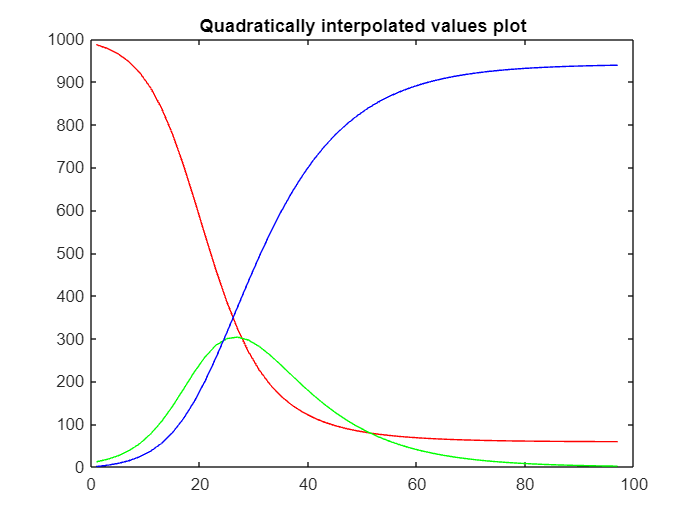


susepInterQuad = zeros(1,size(days,2)); 
infectInterQuad = zeros(1,size(days,2));
recoverInterQuad = zeros(1,size(days,2));


for i=1:n-1  % Quadratic Interpolation for susceptible (flu)
    x = daysInter(1,i);
    x0 = influenza(1,i);
    x1 = influenza(1,i+1);
    x2 = influenza(1,i+2);
    f0 = influenza(2,i);
    f1 = influenza(2,i+1);
    f2 = influenza(2,i+2);

    b0 = (((x-x1)*(x-x2))/((x0-x1)*(x0-x2)))*f0;
    b1 = (((x-x0)*(x-x2))/((x1-x0)*(x1-x2)))*f1;
    b2 = (((x-x0)*(x-x1))/((x2-x0)*(x2-x1)))*f2;
    susepInterQuad(i) = b0 + b1 + b2;
end
for i=1:n-1  % Quadratic Interpolation for infection (flu)
    x = daysInter(1,i);
    x0 = influenza(1,i);
    x1 = influenza(1,i+1);
    x2 = influenza(1,i+2);
    f0 = influenza(3,i);
    f1 = influenza(3,i+1);
    f2 = influenza(3,i+2);

    b0 = (((x-x1)*(x-x2))/((x0-x1)*(x0-x2)))*f0;
    b1 = (((x-x0)*(x-x2))/((x1-x0)*(x1-x2)))*f1;
    b2 = (((x-x0)*(x-x1))/((x2-x0)*(x2-x1)))*f2;
    infectInterQuad(i) = b0 + b1 + b2;
end

for i=1:n-1  % Quadratic Interpolation for recovered (flu)
    x = daysInter(1,i);
    x0 = influenza(1,i);
    x1 = influenza(1,i+1);
    x2 = influenza(1,i+2);
    f0 = influenza(4,i);
    f1 = influenza(4,i+1);
    f2 = influenza(4,i+2);

    b0 = (((x-x1)*(x-x2))/((x0-x1)*(x0-x2)))*f0;
    b1 = (((x-x0)*(x-x2))/((x1-x0)*(x1-x2)))*f1;
    b2 = (((x-x0)*(x-x1))/((x2-x0)*(x2-x1)))*f2;
    recoverInterQuad(i) = b0 + b1 + b2;
end

plot(daysInter(1,1:end-1), susepInterQuad, 'r')
hold on
plot(daysInter(1,1:end-1), infectInterQuad, 'g')
plot(daysInter(1,1:end-1), recoverInterQuad, 'b')
title("Quadratically interpolated values plot")
hold off


EL2susepQuad = sqrt(sum((influenzaTrue(2,2:2:T-2)-susepInterQuad).^2)./n)  % Error for susceptible (flu)

EL2susepQuad = 0.0946

EL2infectQuad = sqrt(sum((influenzaTrue(3,2:2:T-2)-infectInterQuad).^2)./n)  % Error for infected (flu)

EL2infectQuad = 0.0838

EL2recoverQuad = sqrt(sum((influenzaTrue(4,2:2:T-2)-recoverInterQuad).^2)./n)  % Error for susceptible (flu)

EL2recoverQuad = 0.0440

EL2 = [EL2susepLinear EL2infectLinear EL2recoverLinear; EL2susepQuad EL2infectQuad EL2recoverQuad] % 2x3 Matrix (Rows: Linear, Quadratic; Columns: Susceptible, Infected, Recovered)

EL2 =     0.6513    0.5041    0.4129
    0.0946    0.0838    0.0440
